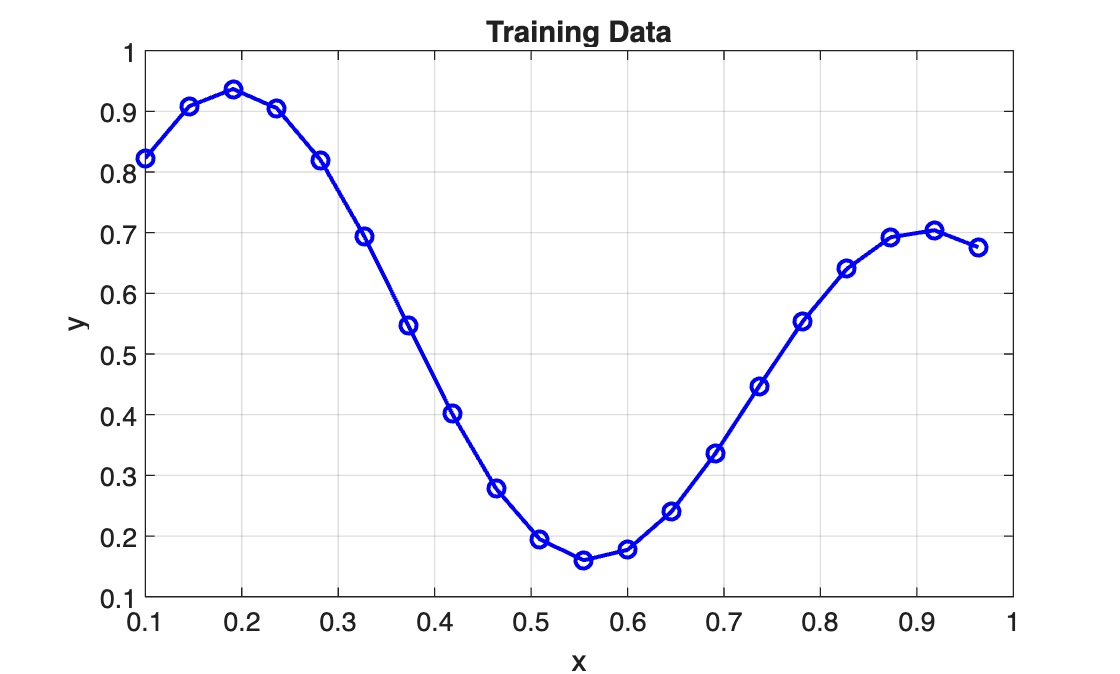

close all; 
clc;

%% Generate Training Data
x = 0.1 : 1/22 : 1;
y = (1 + 0.6 * sin(2*pi*x / 0.7) + 0.3 * sin(2*pi*x)) / 2;

figure;
plot(x, y, 'bo-', 'LineWidth', 1.5); grid on;
xlabel('x'); ylabel('y'); title('Training Data');

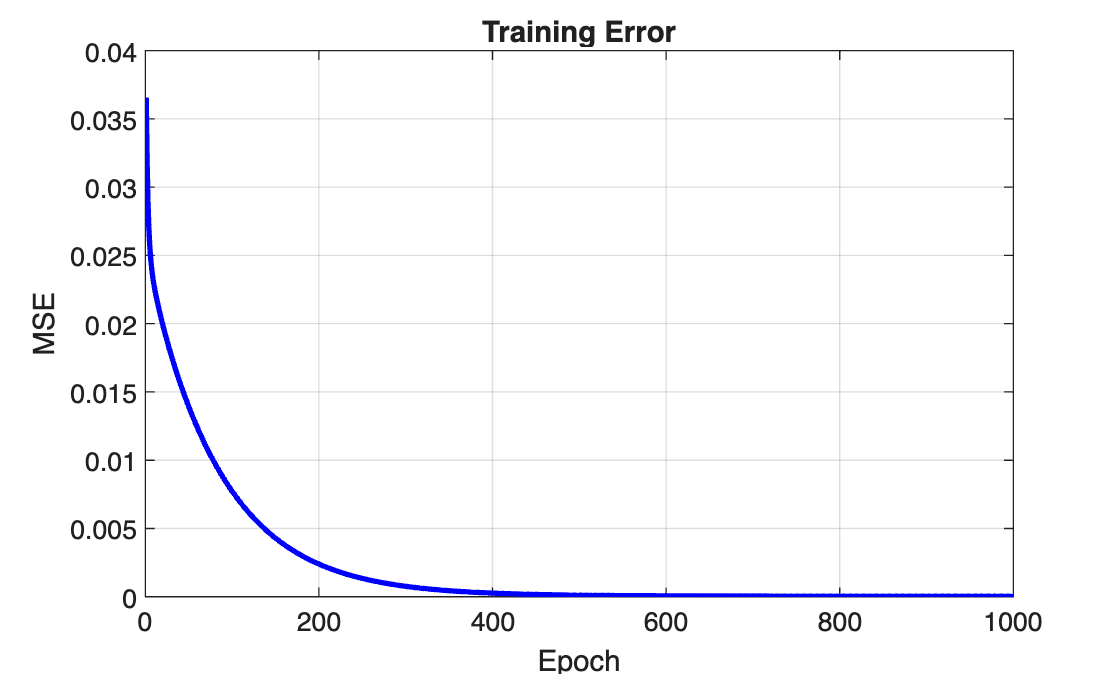

%% RBF Parameters
c1 = 0.19;  r1 = 0.18;
c2 = 0.90;  r2 = 0.17;

%% Compute RBF Activations
N = length(x);
Phi = zeros(N,2);

for i = 1:N
    Phi(i,1) = exp(-(x(i)-c1)^2 / (2*r1^2));
    Phi(i,2) = exp(-(x(i)-c2)^2 / (2*r2^2));
end

%% Output Layer Training (Gradient Descent)
w1 = rand(); w2 = rand(); b = rand();
eta = 0.01;
max_epochs = 1000; 
threshold = 1e-5;
mse_history = zeros(max_epochs,1);

for epoch = 1:max_epochs
    err_sum = 0;

    for i = 1:N
        y_out = w1*Phi(i,1) + w2*Phi(i,2) + b;
        e = y(i) - y_out;
        err_sum = err_sum + e^2;

        w1 = w1 + eta * e * Phi(i,1);
        w2 = w2 + eta * e * Phi(i,2);
        b  = b  + eta * e;
    end

    mse = err_sum / N;
    mse_history(epoch) = mse;

    if mse < threshold
        mse_history = mse_history(1:epoch);
        break;
    end
end

%% Final Prediction
y_pred = zeros(1,N);
for i = 1:N
    phi1 = exp(-(x(i)-c1)^2 / (2*r1^2));
    phi2 = exp(-(x(i)-c2)^2 / (2*r2^2));
    y_pred(i) = w1*phi1 + w2*phi2 + b;
end

%% Training Error Plot
figure;
plot(mse_history, 'b-', 'LineWidth',2);
xlabel('Epoch'); ylabel('MSE'); grid on;
title('Training Error');

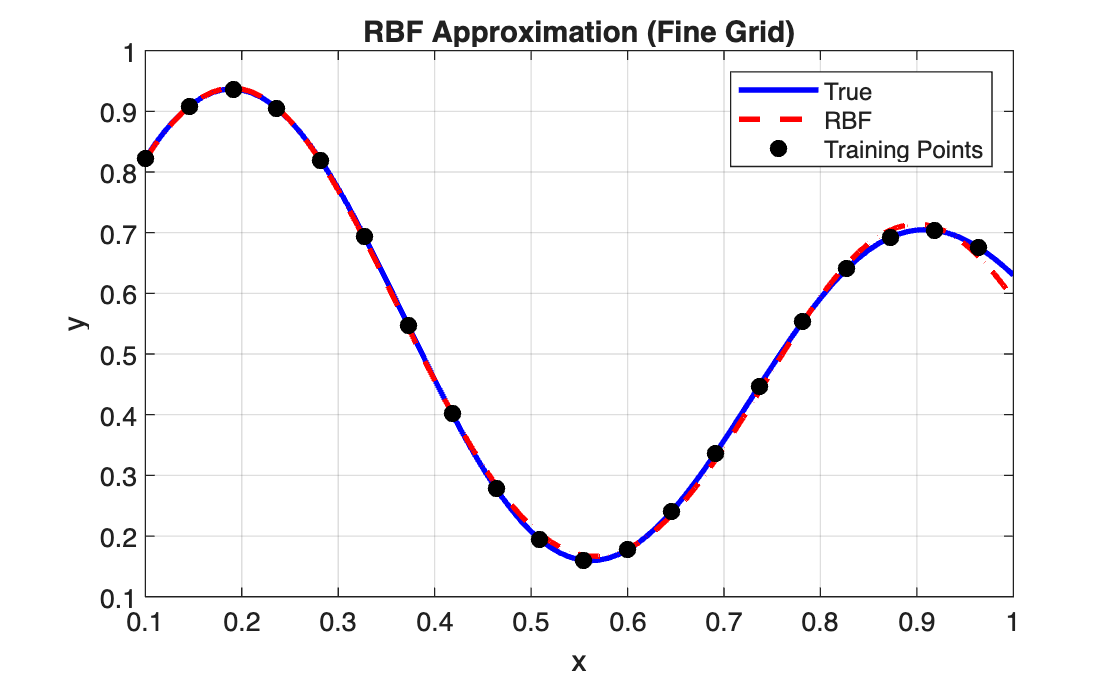


%% Fine Grid Testing
x_test = 0.1:0.01:1;
y_true = (1 + 0.6*sin(2*pi*x_test/0.7) + 0.3*sin(2*pi*x_test))/2;

y_test = zeros(size(x_test));
for i = 1:length(x_test)
    phi1 = exp(-(x_test(i)-c1)^2 / (2*r1^2));
    phi2 = exp(-(x_test(i)-c2)^2 / (2*r2^2));
    y_test(i) = w1*phi1 + w2*phi2 + b;
end

figure;
plot(x_test, y_true, 'b-', 'LineWidth',2); hold on;
plot(x_test, y_test, 'r--', 'LineWidth',2);
plot(x, y, 'ko','MarkerFaceColor','k');
xlabel('x'); ylabel('y');
grid on; title('RBF Approximation (Fine Grid)');
legend('True','RBF','Training Points');